% go to main folder of CLSM spectral analysis

% load data
fp = 'data/raw/testdata';
fn = {'21-xyc-ex405nm_em415-10-735_kaolinite_GSH-CD_pH3.nd2','40-xyc-ex405nm_em415-10-735_US-Y_GSH-CD_pH3.nd2'};
cl = CLSMspectraLab({fullfile(fp,fn{1}),fullfile(fp,fn{2})});

Reading series #1
    ................................
Reading series #1
    ................................


Plotting using input image.


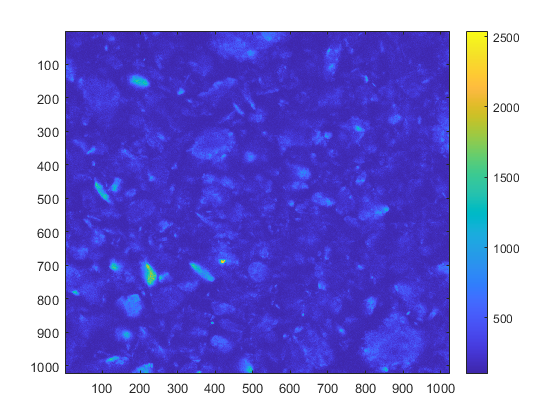

figure; imagesc(cl.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using input image.


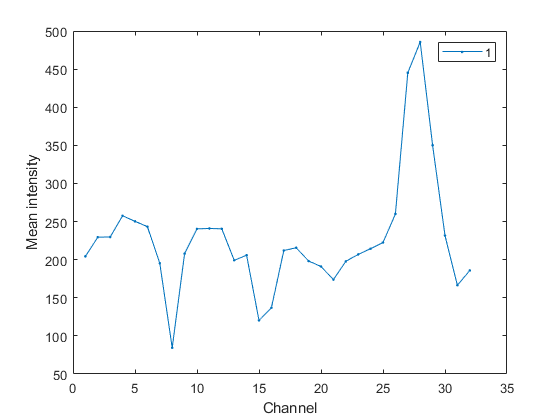

figure; cl.plotChannels([],1)

Plotting using input image.


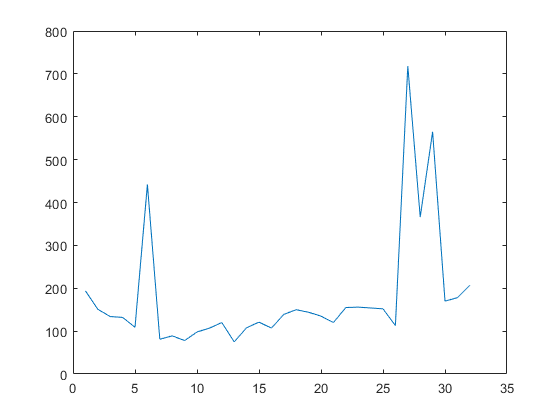

figure; temp = cl.getImageProcessed(1,'reshape','c','x','y'); plot(temp(:,1,1))

cl.bgCorrection = bgCorrection.reference;
Iref = imageStack.import(fullfile(fp,'0-xyc-ex405nm_em415-10-735_interlock-on_dark.nd2')); % import background image

Reading series #1
    ................................


cl.bgCorrection(1).Iref = deal(Iref);
cl.bgCorrection(1).uniformBackgroundFlag = false;
cl = cl.computeBgCorrection;

Computed background correction using input image.


Plotting using background corrected image.


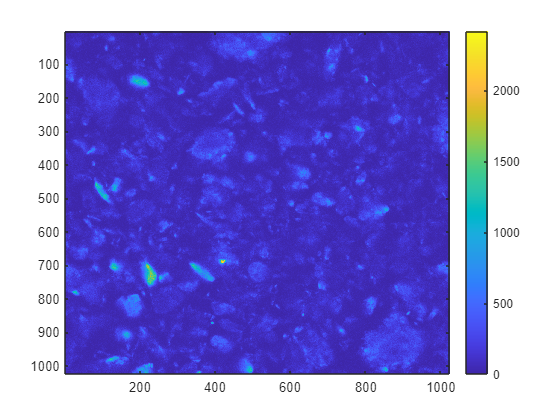

figure; imagesc(cl.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using background corrected image.


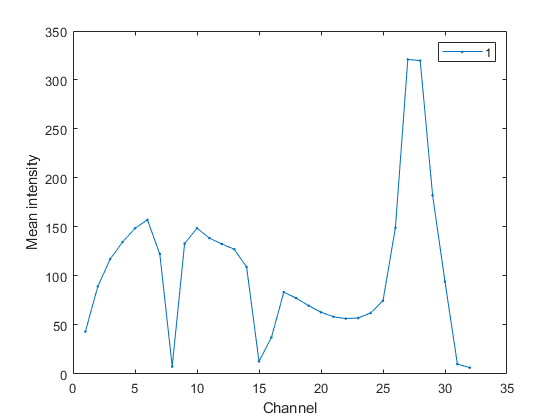

figure; cl.plotChannels([],1)

Plotting using background corrected image.


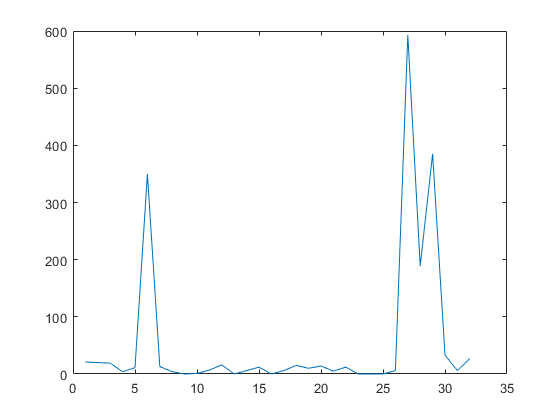

figure; temp = cl.getImageProcessed(1,'reshape','c','x','y'); plot(temp(:,1,1))

cl.normalization = pixelNormalization.max2one;
cl.normalization.dataType = 'integer';
% cl.normalization.point = [27];
cl = cl.computeNormalization;

Computed normalization using background corrected image.


Plotting using normalized image.


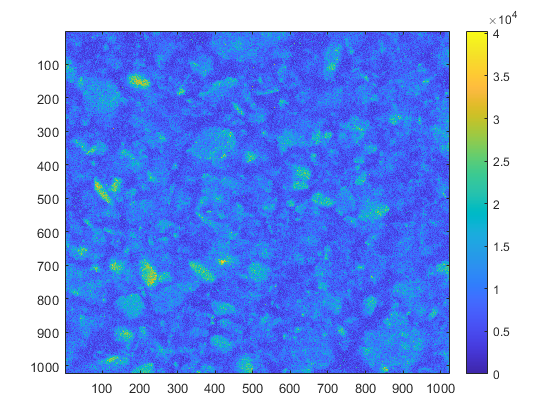

figure; imagesc(cl.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using normalized image.


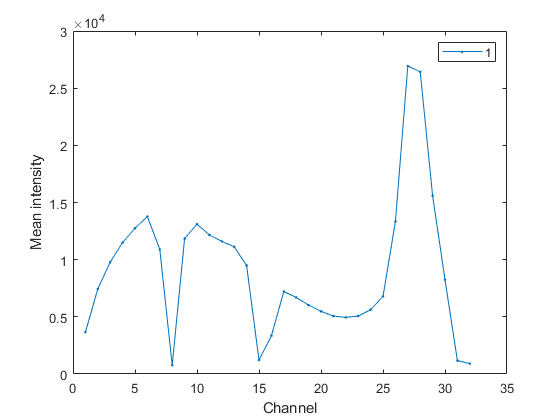

figure; cl.plotChannels([],1)

Plotting using normalized image.


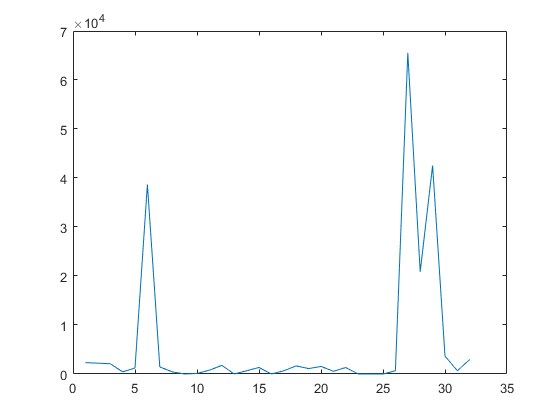

figure; temp = cl.getImageProcessed(1,'reshape','c','x','y'); plot(temp(:,1,1))

cl_bin = cl.getBinnedObj(3);

Plotting using input image.


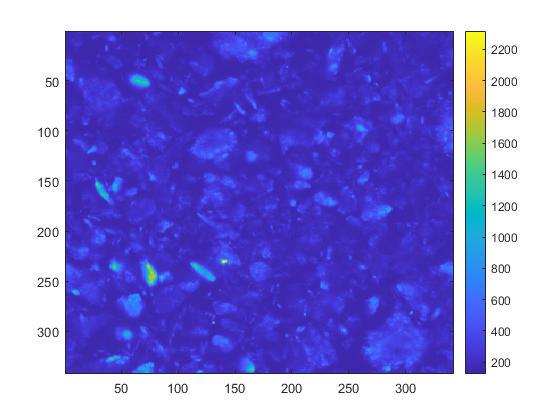

figure; imagesc(cl_bin.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using input image.


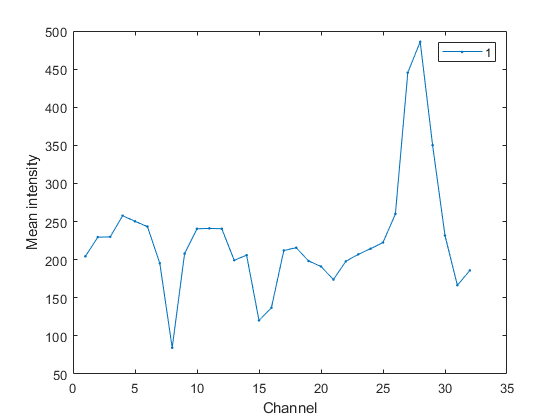

figure; cl_bin.plotChannels([],1)

Plotting using input image.


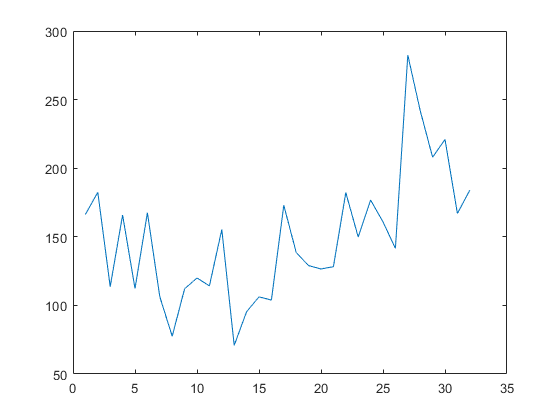

figure; temp = cl_bin.getImageProcessed(1,'reshape','c','x','y'); plot(temp(:,1,1))

cl_bin.bgCorrection = bgCorrection.reference;
Iref = imageStack.import(fullfile(fp,'0-xyc-ex405nm_em415-10-735_interlock-on_dark.nd2')); % import background image

Reading series #1
    ................................


cl_bin.bgCorrection(1).Iref = deal(Iref);
cl_bin.bgCorrection(1).uniformBackgroundFlag = false;
cl_bin.bgCorrection(1).binFactor = cl_bin.binFactor;
cl_bin = cl_bin.computeBgCorrection;

Computed background correction using input image.


Plotting using background corrected image.


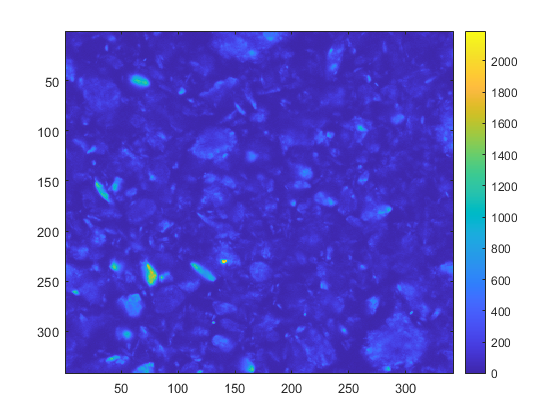

figure; imagesc(cl_bin.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using background corrected image.


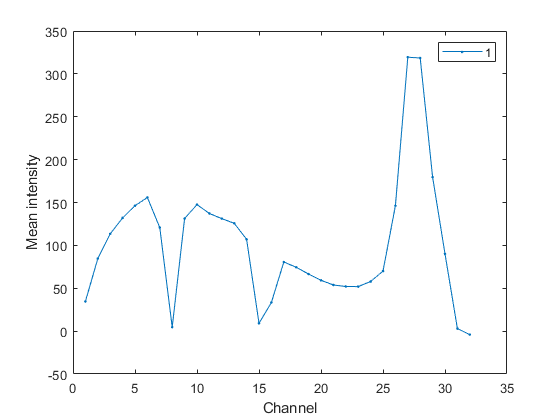

figure; cl_bin.plotChannels([],1)

Plotting using background corrected image.


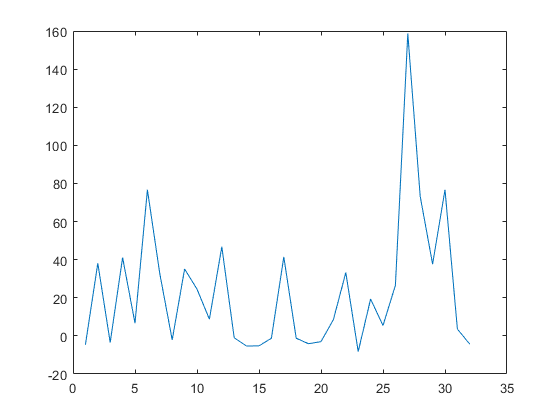

figure; temp = cl_bin.getImageProcessed(1,'reshape','c','x','y'); plot(temp(:,1,1))

cl_bin.normalization = pixelNormalization.max2one;
cl_bin.normalization.dataType = 'integer';
% cl.normalization.point = [27];
cl_bin = cl_bin.computeNormalization;

Computed normalization using background corrected image.


Plotting using normalized image.


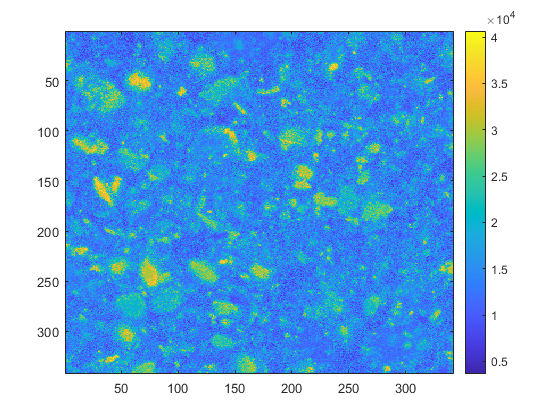

figure; imagesc(cl_bin.getImageProcessed(1,'mean','x','y')); colorbar

Plotting using normalized image.


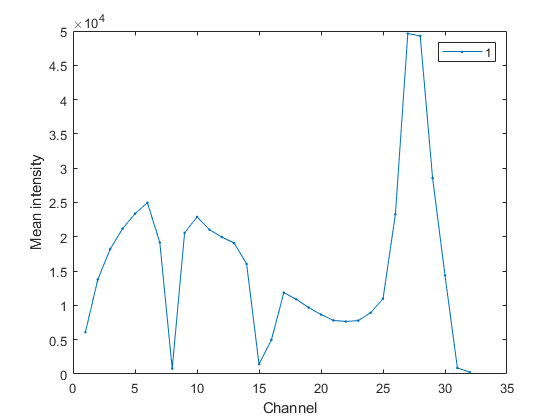

figure; cl_bin.plotChannels([],1)

Plotting using normalized image.


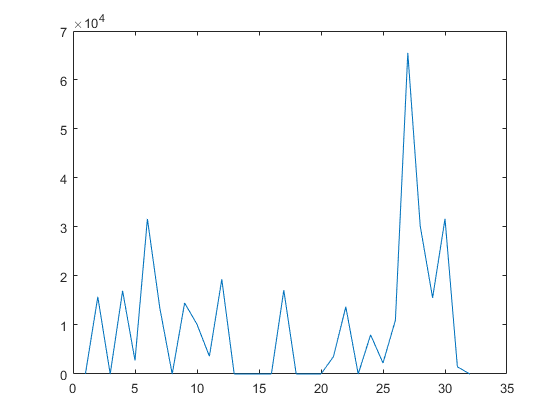

figure; temp = cl_bin.getImageProcessed(1,'reshape','c','x','y'); plot(temp(:,1,1))